RT030_SetCompressorVoltage(0);
i=1;
pressao=0.8;
tic
while(pressao>0.01)
    pressao=RT030_GetPressure();
    lista(:,i)=pressao;
    i=i+1;
end
time = toc;

t=linspace(0,time,length(lista));

figure
plot(t,lista)
title("Malha aberta");
xlabel("Tempo - segundos")
ylabel("Pressão")
grid on;
hold on;

g= fittype('a*exp(b*x)-c*exp(d*x)');
f = fit(t',lista',g)

f =      General model:
     f(x) = a*exp(b*x)-c*exp(d*x)
     Coefficients (with 95% confidence bounds):
       a =       4.126  (-27.46, 35.71)
       b =     -0.0508  (-0.07708, -0.02452)
       c =       3.304  (-28.28, 34.89)
       d =    -0.04425  (-0.0741, -0.01441)

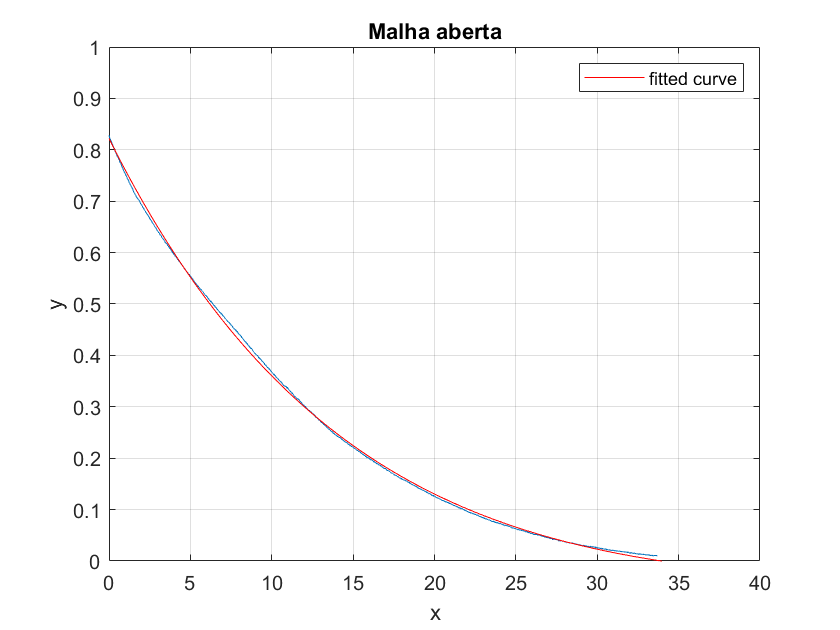

plot(f)
xlim([0 40])
ylim([0 1])